# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

% Using each classifier to predict labels and associated likelihood 
% scores for the test data [4 marks]
% for m_nb
[predictions_nb, scores_nb] = predict(m_nb, test_examples);
% for m_dt
[predictions_dt, scores_dt] = predict(m_dt, test_examples);

% Computing the TPR for each classifier, taking "malignant" as the 
% positive class [3 marks]
% confusion matrix for m_nb
[c_nb,order_nb] = confusionmat(test_labels, predictions_nb)

c_nb =     83     2
     4    53


order_nb = 2×1 categorical array
     Benign 
     Malignant 


% computing the TPR for nb taking malignant as the positive class
tpr_nb = c_nb(2,2) / (c_nb(2,2) + c_nb(2,1)) % higher is better

tpr_nb = 0.9298

% confusion matrix for m_dt
[c_dt,order_dt] = confusionmat(test_labels, predictions_dt)

c_dt =     82     3
     5    52


order_dt = 2×1 categorical array
     Benign 
     Malignant 


%p_dt = sum(diag(c_dt)) / sum(c_dt(1:1:end))
% computing the TPR for dt taking malignant as the positive class
tpr_dt = c_dt(2,2) / (c_dt(2,2) + c_dt(2,1))

tpr_dt = 0.9123


% Computing the FPR for each classifier, taking "malignant" as 
% the positive class [3 marks]
% computing the FPR for nb taking malignant as the positive class
fpr_nb = c_nb(1,2) / (c_nb(1,2) + c_nb(1,1)) % lower is better

fpr_nb = 0.0235

% computing the FPR for dt taking malignant as the positive class
fpr_dt = c_dt(1,2) / (c_dt(1,2) + c_dt(1,1))

fpr_dt = 0.0353


% Generating a Receiver Operating Characteristic (ROC) curve for 
% each classifier and plotting them together on a single graph
% with a legend and labelled axes [4 marks]
% ROC for nb
% Extract the positive class from the scores_nb matrix
scores_pos_nb = scores_nb(1:1:end,2)

scores_pos_nb =     1.0000
    1.0000
    0.0000
    0.0000
    1.0000
    1.0000
    0.0000
    0.0000
    1.0000
    0.0000


% ROC for dt
% Extract the positive class from the scores_dt matrix
scores_pos_dt = scores_dt(1:1:end,2)

scores_pos_dt =      1
     1
     0
     0
     1
     1
     0
     0
     1
     0


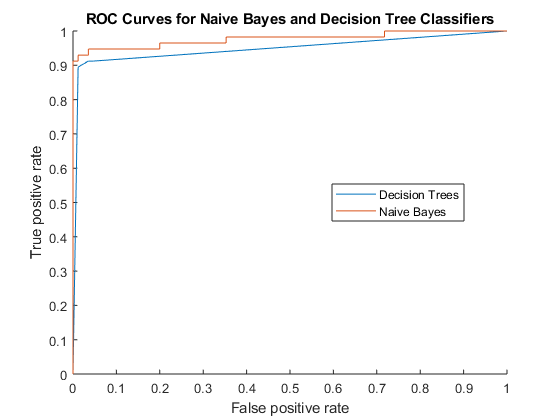

% Generate the ROC Curve for nb
[nb_x,nb_y, ~,AUC_nb] = perfcurve(test_labels, scores_pos_nb, 'Malignant');
% Generate the ROC Curve for dt
[dt_x,dt_y, ~,AUC_dt] = perfcurve(test_labels, scores_pos_dt, 'Malignant');
% Plot the ROC Curve with labelled axis and a legend
hold on
plot(dt_x,dt_y)
plot(nb_x,nb_y)
legend('Decision Trees','Naive Bayes','Location','Best')
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves for Naive Bayes and Decision Tree Classifiers')
hold off


% The AUC values for both classifiers
AUC_nb

AUC_nb = 0.9769

AUC_dt

AUC_dt = 0.9484

% You could also use the 'trapz' function to find
% the AUC values. AUC_nb = trapz(nb_x,nb_y)


% Deciding on the best classifier based on a sensible quantitative 
% comparison between the ROC curves [2 marks]
% In my opinion the Naive Bayes classifier performs better than the
% Decision Tree classifier because it peaks at a TPR of just over 
% 0.9 and maintains an FPR of 0, whereas the Decision Tree classifier
% only peaks at a TPR of under 0.1 when the FPR is 0. After that,
% the DT classifier starts to digress from the 0 FPR and it never
% manages to get a higher TPR value than the Naive Bayes classifier.
% In addition the Naive Bayes classifier has a higher AUC value (97%)
% compared to the Decision Tree classifier (94%), therefore it's
% much more accurate.